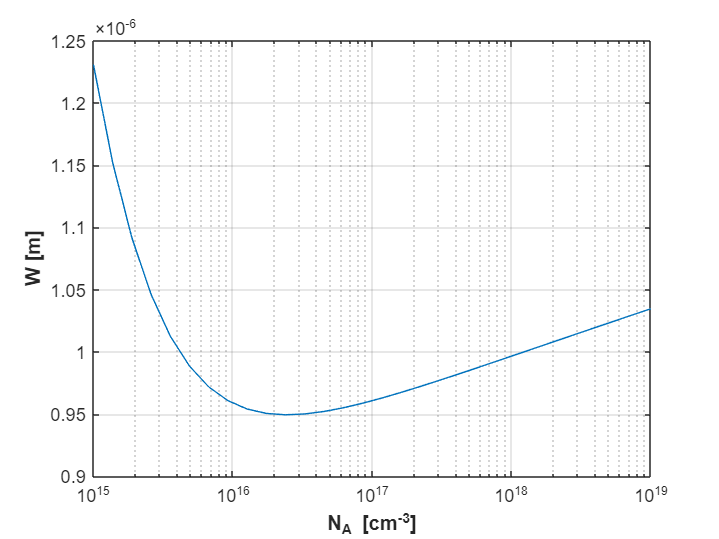

%Spessore SCR
%W=sqrt(2EpsilonS/q *VBI * (1/Na + 1/Nd));
q=1.602e-19; %C
epsilon0=8.85e-12; %F/m
epsilonS=11.9*epsilon0;
NA_v2=logspace(15,19,30);
T=300;%K
K=8.6167e-5; %eV/K
K1=K*q; %J/K
ni=1.45e10; %cm^-3
Vt=K1*T/q; %V - tensione termica

%%Se invece fissiamo ND a 10^15 e variamo NA è possibile visualizzare più
%%chiaramente l'aumento di W per Na alte

NDv1=1e15; %cm^-3
W_NA=sqrt(2*epsilonS*(1/q).*(K1*T*(1/q)*log(NA_v2*NDv1/ni^2)).*(1./NA_v2 + 1/NDv1))/1000; %metri
figure(9)
semilogx(NA_v2,W_NA)
grid on 
xlabel(" N_A [cm^{-3}] ","FontWeight","bold")
ylabel(" W [m] ","FontWeight","bold")